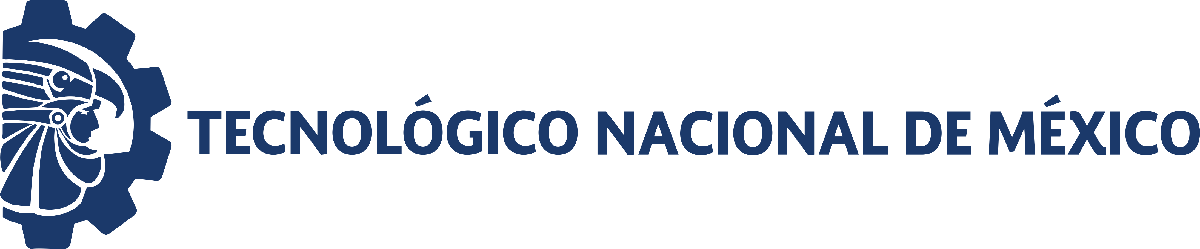                                 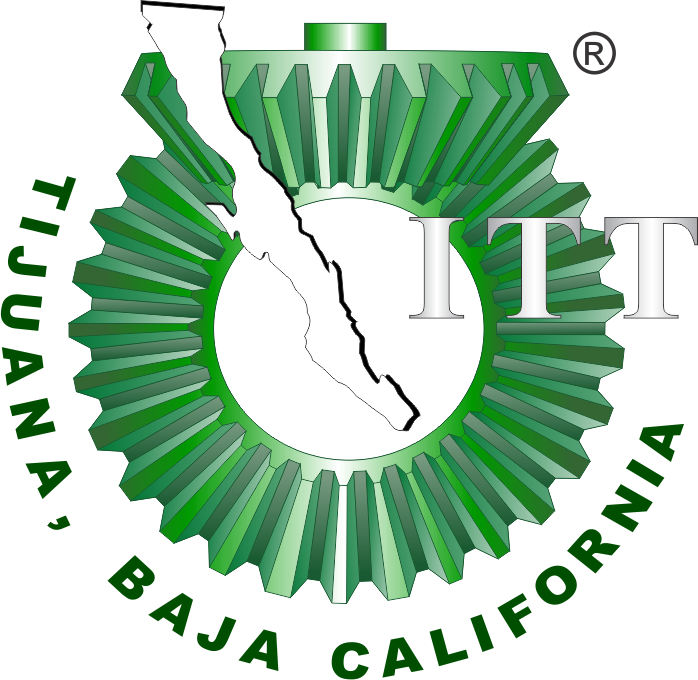

# Práctica 1: Leyes de Crecimiento Exponencial

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información General

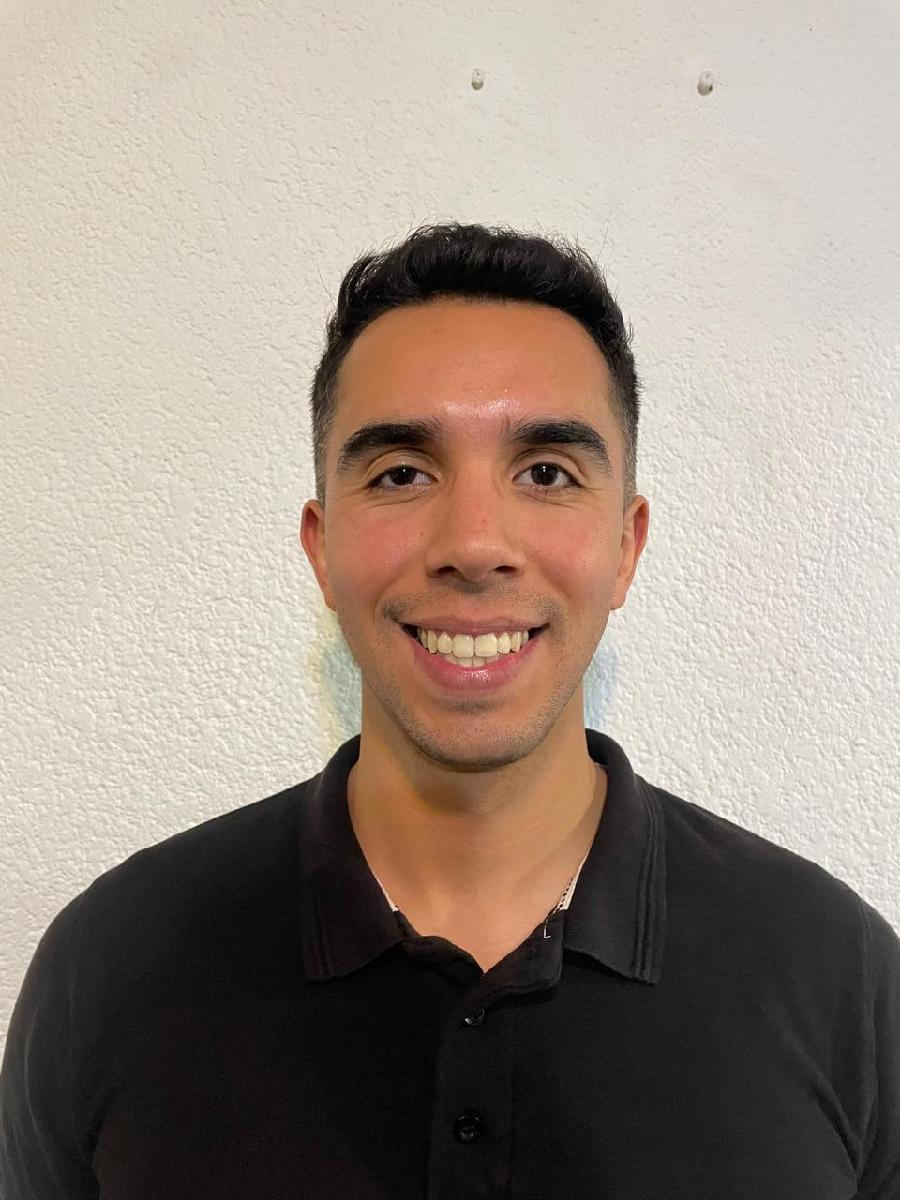

Nombre del alumno: **Carlos Andrés Gil Gárate**

Número de control: **21212743**

Correo institucional: **21212743@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Simulation Data

clc; clear; close all; warning('off','all');

## Expnential Growth Law


$$\overset{\cdot }{\dot{x} } =\textrm{kx}$$


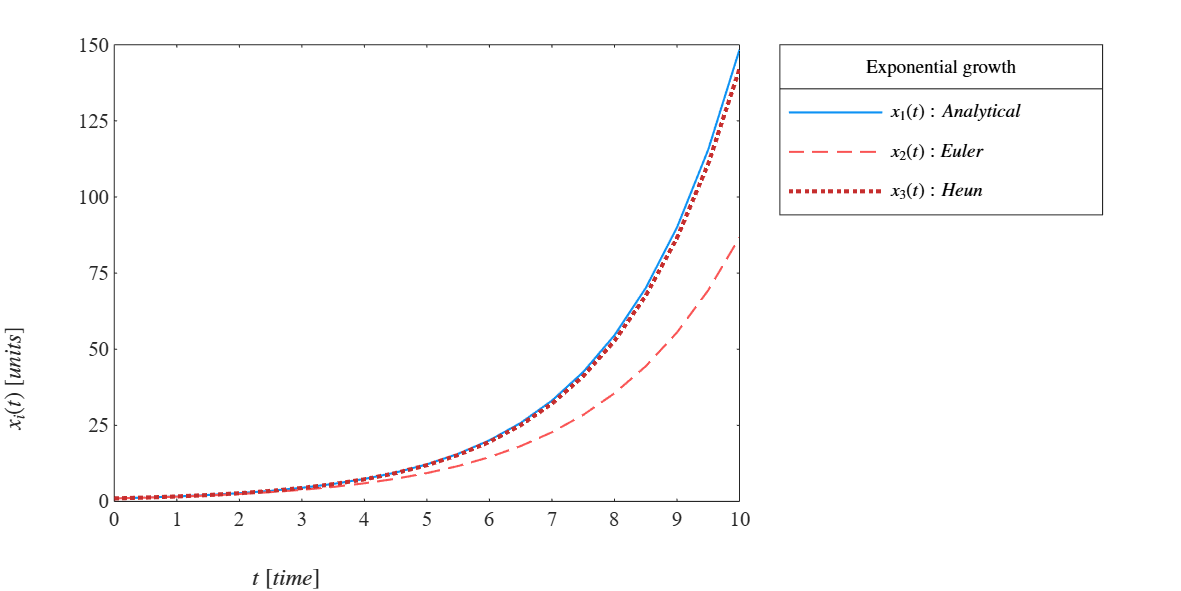

dt = 0.5; %Integration Step 
x0 = 1; %Initial condition
k = 0.5; %Growth rate (parameter)
tend = 10; % Simulation end time 

[t,x1,x2,x3] = sys_exgrowth(dt,x0,k,tend); %Funcion para una resolucion analitica del crecimiento
plotl1(t,x1,x2,x3) %grafica de los resultados

function [t,x1,x2,x3] = sys_exgrowth(dt,x0,k,tend)
    t = (0:dt:tend)'; %arreglo del tiempo
    n = round(tend/dt); %cantidad de iteraciones
    x2 = zeros(numel(t),1); x2(1) = x0; 
    x3 = zeros(numel(t),1); x3(1) = x0; 

%% Analytical solution
    x1 = x0*exp(k*t); %Valor real de la funcion

%% Euler's method (metodo iterativo)
    for i = 1:n
        x2(i+1) = x2(i) + (k*x2(i))*dt; 
    end 
   
%% Heun's method 
    for i = 1:n 
        [fx3] = f(x3(i)); %pendiente
        x3n = x3(i) + fx3*dt;

        [fx3n] = f(x3n); %segunda pendiente
        x3(i+1) = x3(i) + (fx3 + fx3n)*dt/2; %promedio de ambas pendientes para aproximar el valor. 
    end 
    
    function [dx3] = f(x3) %funcion que trabaja respecto al ciclo for anterior. 
        dx3 = k*x3; 
    end 

end 

function plotl1(t,x1,x2,x3) 
    set(figure(1),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,10])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    mycolors = [13, 146, 244; 249, 84, 84; 198, 46, 46;]/255;
    hold on; box on; grid off; colororder(mycolors)

    plot(t,x1,'-','LineWidth',1)
    plot(t,x2,'--','LineWidth',1)
    plot(t,x3,':','LineWidth',2)
    xlabel('$t$ $[time]$', 'Interpreter', 'Latex')
    ylabel('$x_i(t)$ $[units]$', 'Interpreter', 'Latex')
    L = legend('$x_1(t):Analytical$','$x_2(t):Euler$', '$x_3(t):Heun$');
    set(L,'Interpreter','Latex','Location','NorthEastOutside')
    title(L,'Exponential growth')
    xlim([0 10]); xticks(0:1:10);
    ylim([0 150]); yticks(0:25:150);


    exportgraphics(gcf,'exponential growth.pdf','ContentType','vector')
end

## Expnential Decay Law

###     Ejercicio Adicional 


$$\overset{\cdot }{\dot{x} } =-\textrm{kx}$$


Look for the point in the plot where $x\left(t\right)=\frac{x_0 }{2}\left(\textrm{half}-\textrm{life},t_{\frac{1}{2}} \right)$ and compute the decay rate of the bioprocess, where $k=\frac{\textrm{ln2}}{t_{\frac{1}{2}} }$

Buscamos la relacion de la **vida media **de un fármaco con la **taza de decrecimiento**, por lo que, en otras palabras, buscamos en la gráfica el punto en el que $x_1 \left(t\right)$ es la mitad del valor inicial (1), o sea, 0.5 y el punto en el tiempo $t$ en el que coinciden. El resultado es $x\left(t\right)$1.38. 

dt = 0.5; %Integration Step 
x0 = 1; %Initial condition 
k = 0.5; %Growth rate (parameter)
tend = 10; % Simulation end time 


    t[min]     N32      N35      N36      N45 
    ______    _____    _____    _____    _____

       0          0        0        0        0
      15      43.68    35.47    51.35    34.39
      30      64.31    55.89    69.07    49.08
      45       73.6    62.69    77.82    59.34
      60      80.95    70.15     84.3    68.31
      75      82.24    72.85     88.4    72.85
      91      85.59    75.44    92.07    76.74
     105       88.4    77.92    95.42    80.08
     120      90.56    78.03    97.15    83.65
     150      90.78    80.52    97.69    86.78
     180      90.24    80.73    97.69    88.83
     210       92.4     80.3    98.23    89.91



[t,x1,x2,x3] = sys_exdecay(dt,x0,k,tend); %Funcion para una resolucion analitica del crecimiento
plotl2(t,x1,x2,x3) %grafica de los resultados

function [t,x1,x2,x3] = sys_exdecay(dt,x0,k,tend)


Sample Size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
t-Student value: 2.2281
Adjusted R-squared: 0.99485
Corrected AIC (n/pars < 40): 53.197    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

       k          0.040504    0.0017568    0.0039143    0.036589    0.044418    5.3239e-10
       beta         89.847      0.82673       1.8421      88.004      91.689    1.0668e-16



    t = (0:dt:tend)'; %arreglo del tiempo


Sample Size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
t-Student value: 2.2281
Adjusted R-squared: 0.99627
Corrected AIC (n/pars < 40): 46.5589    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

       k          0.037453    0.0013753    0.0030643    0.034388    0.040517    1.0315e-10
       beta         79.417      0.65053       1.4495      77.967      80.866    3.3367e-17



    n = round(tend/dt); %cantidad de iteraciones


Sample Size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
t-Student value: 2.2281
Adjusted R-squared: 0.98763
Corrected AIC (n/pars < 40): 65.0565    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

       k          0.041963    0.0028129    0.0062676    0.035695     0.04823     3.686e-08
       beta         95.959       1.3342       2.9728      92.986      98.932    6.5864e-15



    x2 = zeros(numel(t),1); x2(1) = x0; 


Sample Size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
t-Student value: 2.2281
Adjusted R-squared: 0.99032
Corrected AIC (n/pars < 40): 60.4553    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

       k          0.025988    0.0015189    0.0033843    0.022604    0.029373    9.8118e-09
       beta         87.728       1.4513       3.2337      84.494      90.962    3.7311e-14



    x3 = zeros(numel(t),1); x3(1) = x0; 

%% Analytical solution
    x1 = x0*exp(-k*t); %Valor real de la funcion

%% Euler's method (metodo iterativo)
    for i = 1:n
        x2(i+1) = x2(i) + (-k*x2(i))*dt; 
    end 
   
%% Heun's method 
    for i = 1:n 
        [fx3] = f(x3(i)); %pendiente
        x3n = x3(i) + fx3*dt;

        [fx3n] = f(x3n); %segunda pendiente
        x3(i+1) = x3(i) + (fx3 + fx3n)*dt/2; %promedio de ambas pendientes para aproximar el valor. 
    end 
    
    function [dx3] = f(x3) %funcion que trabaja respecto al ciclo for anterior. 
        dx3 = -k*x3; 
    end 

end 

function plotl2(t,x1,x2,x3) 
    set(figure(2),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,10])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    mycolors = [13, 146, 244; 249, 84, 84; 198, 46, 46;]/255;
    hold on; box on; grid off; colororder(mycolors)

    plot(t,x1,'-','LineWidth',1)
    plot(t,x2,'--','LineWidth',1)
    plot(t,x3,':','LineWidth',2)
    xlabel('$t$ $[time]$', 'Interpreter', 'Latex')
    ylabel('$x_i(t)$ $[units]$', 'Interpreter', 'Latex')
    L = legend('$x_1(t):Analytical$','$x_2(t):Euler$', '$x_3(t):Heun$');
    set(L,'Interpreter','Latex','Location','NorthEastOutside')
    title(L,'Exponential growth')
    xlim([0 10]); xticks(0:1:10);
    ylim([0 1.1]); yticks(0:0.1:150);

    exportgraphics(gcf,'exponential decay.pdf','ContentType','vector')
end

## First order pharmacokinetics [modified exponential decay]: Controlled drug delivery by nanohydrogels 


$$\overset{\ldotp }{x} =\beta \left(1-e^{-\textrm{kt}} \right)$$


Contiene 2 parametros:

**Beta:** tiende a un valor de liberacion del farmarco y 

**K:** representa la taza de liberacion, 

Por ultimo se analiza el error en estado estacionario, este corresponde a que el farmaco no tiene una liberacion de 100% en el sistema. 

**Reference: **González‐Ayón, M. A., Sañudo‐Barajas, J. A., Picos‐Corrales, L. A., & Licea‐Claverie, A. (2015). PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil. *Journal of Polymer Science Part A: Polymer Chemistry*, *53*(22), 2662-2672. doi: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

clc; clear; close all
sys = readmatrix('data.csv');
t = round(sys(:,1));
x1 = sys(:,2); x2 = sys(:,3); x3 = sys(:,4); x4 = sys(:,5);

phi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


T = array2table([t,x1,x2,x3,x4],'VariableNames',{'t[min]','N32','N35','N36','N45'}); disp(T)

## Nonlinear regression and biostatistics 

rho = [0.1,100]; %Metodo auristico para evitar divergencia en el resultado.
%A continuacion, los resultados son una estructura dentro de otra.
mdl_x1 = pharmacokinetics(t,x1,rho); y1 = mdl_x1.Fitted; %Nanohidrogel N32 
mdl_x2 = pharmacokinetics(t,x2,rho); y2 = mdl_x2.Fitted; %Nanohidrogel N35 
mdl_x3 = pharmacokinetics(t,x3,rho); y3 = mdl_x3.Fitted; %Nanohidrogel N36 
mdl_x4 = pharmacokinetics(t,x4,rho); y4 = mdl_x4.Fitted; %Nanohidrogel N45
plotdata(t,x1,x2,x3,x4,y1,y2,y3,y4)

### Functions 

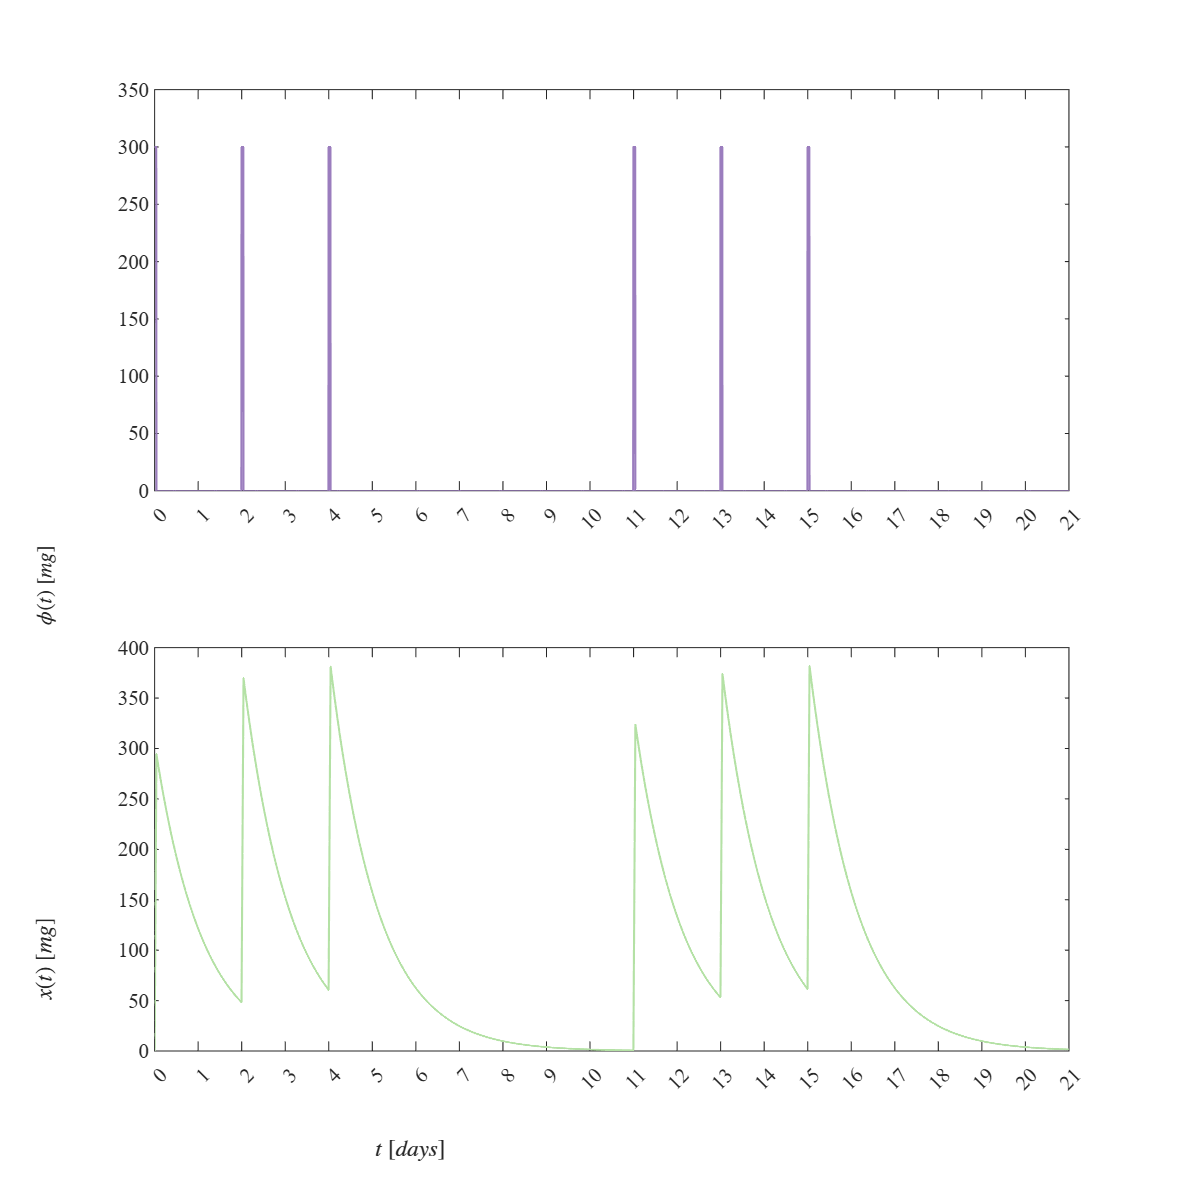

function mdl = pharmacokinetics(to,xo,rho)
    function xi = model(rho,t)
        k = rho(1); beta = rho(2); 
        xi = beta*(1 - exp(-k*t));

    end 

    mdl =  fitnlm(to,xo,@model,rho); 

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4)); %Valor P 
    alpha = 0.05; 
    CI95 = coefCI(mdl,alpha); %Coeficientes 
    dof = mdl.DFE; 
    tval = tinv(1 - alpha/2,dof); %Intervalos de Confianza 
    MoE = SE*tval; %Margen de error
    Parameters = ['k   ';'beta']; %Parametros
    Results = table(Parameters, Estimate,SE,MoE,CI95,pvalue);

    fprintf(['\nSample Size (n): ',num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ',num2str(numel(rho))])
    fprintf(['\nDegrees of freedom: ',num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nAdjusted R-squared: ', num2str(mdl.Rsquared.Adjusted)])
    fprintf(['\nCorrected AIC (n/pars < 40): ',num2str(mdl.ModelCriterion.AICc), ])

    disp(Results)
end

function plotdata(t,x1,x2,x3,x4,y1,y2,y3,y4)
    set(figure(3),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,10])
    set(gca,'FontName','Times New Toman')
    fontsize(10,'points')
    colores = [155, 125, 190;
                55, 115, 120;
                180, 225, 165;
                230, 185, 235;
                ]/255;
    % shuffledcolors = mycolors(randperm(size(mycolors,1)),:); Sirve para colores aleatorios
    hold on; box on; grid off; colororder(colores)

    %Experimental data
    plot(t,x1,'x','MarkerSize',5,'LineWidth',1)
    plot(t,x2,'o','MarkerSize',5,'LineWidth',1)
    plot(t,x3,'square','MarkerSize',5,'LineWidth',1)
    plot(t,x4,'diamond','MarkerSize',5,'LineWidth',1)
    
    % Fitted values
    plot(t,y1,'-','LineWidth',1)
    plot(t,y2,'-','LineWidth',1)
    plot(t,y3,'-','LineWidth',1)
    plot(t,y4,'-','LineWidth',1)

    xlabel('$t$ $[min]$','Interpreter','Latex')
    ylabel('$Cumulative drug release$ $[\%]$','Interpreter','Latex')
    xlim([0 220]); xticks(0:20:220)
    ylim([0 100]); yticks(0:10:100)

    L = legend('$x_1(t):N32$','$x_2(t):N35-VP15$', '$x_3(t):N36-2MBA3$','$x_4(t):N45-2MBA12$');
    set(L,'Interpreter','Latex','Location','SouthEast','Box','Off')

    exportgraphics(gcf,'nanohydrogels.pdf','ContentType','vector')
    exportgraphics(gcf,'nanohydrogels.png','Resolution',600)
    exportgraphics(gcf,'nanohydrogels.jpg','Resolution',600)
    print('nanohydrigels','-dsvg')
    print('nanohydrigels','-depsc')

end

### **Chemotherapy dynamics in the blood compartment **

Assume that the chemotherapy drug within the blood compartment follows a first-order kinetics. Let us apply the modified exponential decay to ilustrate the dynamics of this drug when administered with the following scheme: 

- **Protocol:** (3 Imatinib intakes every 2 days + 7 days of rest)* 2cycles.

- **Dosing: **300 mg/day per dose.

- **Application frequency:** One dose every 2 days.

- **Doses per cycle:** 3 doses.

- **Number of cycles: **2 cycles.

- **Imatinib biological half-life [**$t_{1\;/2}$**]: **18 hours [0.75 days] http://go.drugbank.com/drugs/DB00619

- **ODE:** $\overset{\ldotp }{x} =\phi \left(t\right)-\mu x$

### **Time: Hours**

clc; clear; close all; warning('off','all')
dt = 0.1; dose = 300; mu = log(2)/18; tend = 21*24; 
t = (0:dt:tend)';
phi = zeros(tend/dt+1,1)

#### Cycle 1

phi(1:1/dt) = dose;
phi(2*24/dt:(2*24+1)/dt) = dose;
phi(4*24/dt:(4*24+1)/dt) = dose;


#### Cycle 2 

phi(11*24/dt:(11*24+1)/dt) = dose;
phi(13*24/dt:(13*24+1)/dt) = dose;
phi(15*24/dt:(15*24+1)/dt) = dose;

[t,x] = sys_chemo(dt,mu,phi,tend);
plotchemo(t/24,phi,x,'hours')

### Functions

function [t,x] = sys_chemo(dt,mu,phi,tend)
    t = (0:dt:tend)';
    n = round(tend/dt);
    x = zeros(numel(t,1));

    % Heun's method
    for i = 1:n
        [fx] = f(x(i),phi(i));
        xn = x(i) + fx*dt;

        [fxn] = f(xn,phi(i));
        x(i+1) = x(i) + (fx + fxn)*dt/2;
    end

    function [dx] = f(x,phi)
        dx = phi - mu*x;
    end
end

function plotchemo(t,phi,x,time)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,20])

    subplot(2,1,1)
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,phi,'-','LineWidth',1,'Color',[0.6078, 0.4902, 0.7451])
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$\phi(t)$ $[mg]$','Interpreter','Latex')
    xlim([0 21]); xticks(0:1:21)
    ylim([0 350]); yticks(0:50:350)

    subplot(2,1,2)
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',[0.7059, 0.8824, 0.6471])
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$ $[mg]$','Interpreter','Latex')
    xlim([0 21]); xticks(0:1:21)
    ylim([0 400]); yticks(0:50:400)

    exportgraphics(gcf,['chemotherapy', time,'.pdf'],'ContentType','vector')
end